# MidTerm

# Name - Vinay Patil

# Net Id - vpatil3

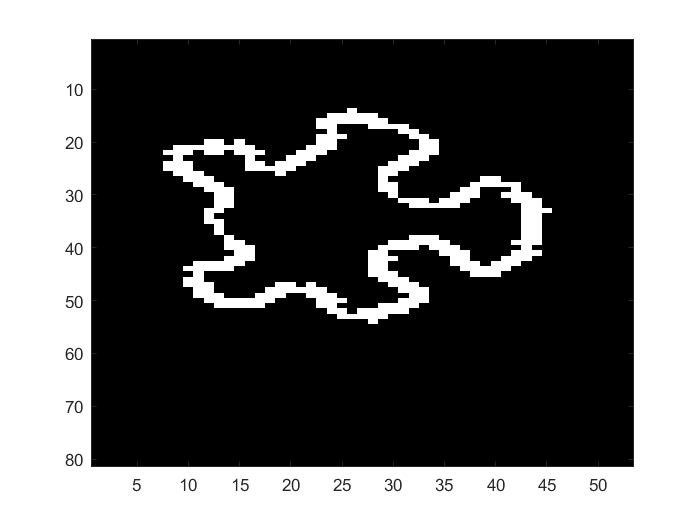

%Preprocessing steps for orange_piece.jpg
orangePiece = double(imread("orange_piece.jpg"));
%Resize orangePiece to lower the resolution by a factor of 5
newOrangePieceRows = ceil(size(orangePiece,1)/5);
newOrangePieceCols = ceil(size(orangePiece,2)/5);
orangePiece = imresize(orangePiece,[newOrangePieceRows newOrangePieceCols]);
%Changing to grayScale
orangePiece = 0.2989*orangePiece(:,:,1)+0.5870*orangePiece(:,:,2)+0.1140*orangePiece(:,:,3);
%Removing noise from the image
orangePieceGray = medfilt2(orangePiece);
%Detecting edges and binarizing
ksx = reshape([-1 -2 -1 0 0 0 1 2 1], 3, 3 );
ksy = ksx';
gx = conv2(orangePieceGray, ksx, 'same');
gy = conv2(orangePieceGray, ksy, 'same');
orangePiece = sqrt(gx.^2 + gy.^2);
orangePiece = orangePiece>330;
angle = 45;
orangePiece = rotatePiece(orangePiece,angle);
figure
imagesc(orangePiece);

%Finding x_c and y_c
[x_coord,y_coord] = find(orangePiece >0);
x_c = round(mean(x_coord));
y_c = round(mean(y_coord));

%Finding angles for orange_piece.jpg edge points
dir_grad_piece = atan2(gy,gx);
dir_grad_piece(orangePiece==0) = 0;
dir_grad_piece = round(dir_grad_piece*180/pi,1,'significant');

%Getting unique angles and ignoring non-edge angles i.e 0
unique_angles = unique(dir_grad_piece);
unique_angles = unique_angles(unique_angles~=0);

%Constructing R-Table
R_Table = struct;
count = 1;
for phi_degree=unique_angles'
    [x,y] = find(dir_grad_piece==phi_degree);
    x_prime = x_c - x;
    y_prime = y_c - y;
    r = sqrt(x_prime.^2 + y_prime.^2);
    alpha_rad = atan2(y_prime,x_prime);
    R_Table(count).phi = phi_degree;
    R_Table(count).alpha = round(alpha_rad*180/pi)';
    R_Table(count).length = r';
    count = count + 1;
end

struct2table(R_Table);


%Preprocessing steps for main.jpg
colormap('gray')

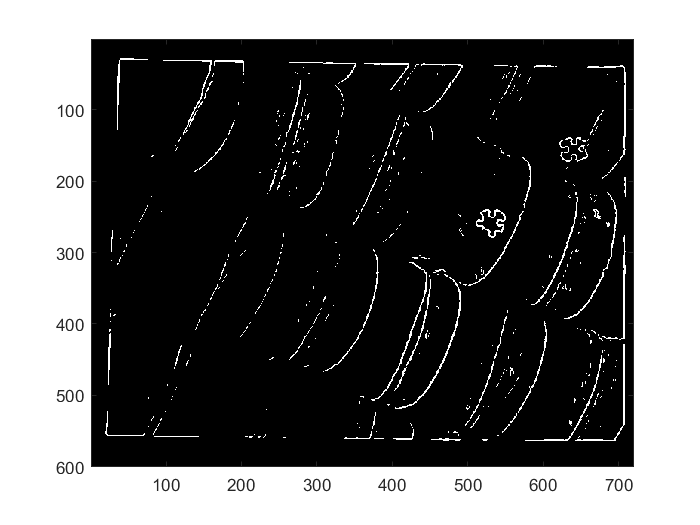

main = double(imread("main.jpg"));
%Resize main to lower the resolution by a factor of 5
newMainRows = ceil(size(main,1)/5);
newMainCols = ceil(size(main,2)/5);
main = imresize(main,[newMainRows newMainCols]);
%Changing to grayScale
main = 0.2989*main(:,:,1)+0.5870*main(:,:,2)+0.1140*main(:,:,3);
%Removing noise from the image
mainGray = medfilt2(main);
%Detecting edges and binarizing
ksx = reshape([-1 -2 -1 0 0 0 1 2 1], 3, 3 );
ksy = ksx';
gx = conv2(mainGray, ksx, 'same');
gy = conv2(mainGray, ksy, 'same');
main = sqrt(gx.^2 + gy.^2);
main = main>250;
imagesc(main);

## 1) Generalized Hough Transform

%Finding angles for main.jpg edge points
dir_grad_main = atan2(gy,gx);
dir_grad_main(main==0) = 0;
dir_grad_main = round(dir_grad_main*180/pi,1,'significant');

%Getting unique angles and ignoring non-edge angles i.e 0
unique_angles = unique(dir_grad_main);
unique_angles = unique_angles(unique_angles~=0);

%Building accumulation matrix
rows = size(main,1);
cols = size(main,2);
no_of_rotations = 360/45;
acc_matrix = zeros(rows,cols,no_of_rotations);
R_Table_New = R_Table;

for rot=0:no_of_rotations-1
    if(rot>0)
        R_Table_New = rotatePhi(R_Table,rot);
    end
    
    for phi_degree=unique_angles'
        [x,y] = find(dir_grad_main==phi_degree);
        matchedLogical = [R_Table_New.phi]==phi_degree;
        
        if sum(matchedLogical)==1
            match = R_Table_New(matchedLogical);
            nums = length(match.alpha); % The length vector will also be of same size, can consider either here
            for i=1:nums
                x_candidate = round(x + match.length(i)*cos(match.alpha(i)*pi/180));
                y_candidate = round(y + match.length(i)*sin(match.alpha(i)*pi/180));
                
                %Getting valid coordintes for accumulator matrix
                coord_x = x_candidate<=rows & x_candidate>0;
                coord_y = y_candidate<=cols & y_candidate>0;
                valids = coord_x & coord_y;
                x_candidate = x_candidate(valids);
                y_candidate = y_candidate(valids);
                
                count = sum(valids);
                for j=1:count
                    acc_matrix(x_candidate(j),y_candidate(j),rot+1) = acc_matrix(x_candidate(j),y_candidate(j),rot+1) + 1;
                end
            end
        end
    end
end

%Finding optimal accumulation matrix
max_val = 0;
x_cen = 0;
y_cen = 0;
rot_index = 0;
for h=1:8
    acc = acc_matrix(:,:,h);
    %acc =  acc./sum(acc(:));
    [M,X] = max(acc(:))
    if(M>max_val)
        max_val = M;
        [x_cen,y_cen] = ind2sub(size(acc),X);
        rot_index = h;
    end
end

M = 17

X = 323051

M = 3

X = 393832

M = 9

X = 317661

M = 0

X = 1

M = 10

X = 314059

M = 0

X = 1

M = 8

X = 172305

M = 3

X = 377020

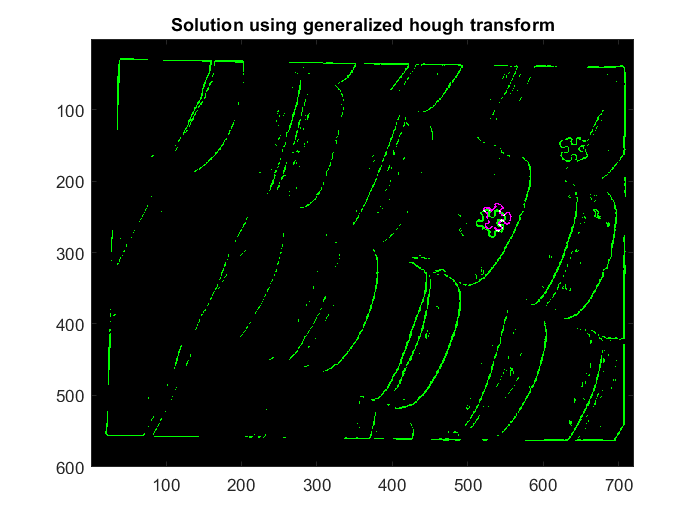


generated_shape = zeros(rows,cols);
table = rotatePhi(R_Table,rot_index-1);

for k=1:length(table)
    nums = length(table(k).alpha);
    for i=1:nums
        xloop = round(x_cen-(table(k).length(i)*cos(table(k).alpha(i)*pi/180)));
        yloop = round(y_cen-(table(k).length(i)*sin(table(k).alpha(i)*pi/180)));
        if xloop>0 && yloop>0 && xloop<=rows && yloop<=cols
            generated_shape(xloop,yloop) = 1;
        end
    end
end

%Combining the images
fused_img = imfuse(main, generated_shape);
figure
imagesc(fused_img);
title('Solution using generalized hough transform');

%Function to rotate the R-Table

function new_table = rotatePhi(table,rot)
for k=1:length(table)
    temp = table(k).phi + rot*45;
    
    if(temp>180)
        x = mod(temp,360);
        if(x>180)
            x = -180 + mod(x,180);
        end
        temp = x;
    end
    table(k).phi = temp;
    table(k).alpha = table(k).alpha + rot*45;
end
new_table = table;
end

%Function to rotate the puzzle piece
function rotimg = rotatePiece(piece,angle)
rotimg=zeros(size(piece));
rotmat=zeros(2,2);
rotmat(1,1)=cos(angle*pi/180);
rotmat(1,2)=-sin(angle*pi/180);
rotmat(2,1)=sin(angle*pi/180);
rotmat(2,2)=cos(angle*pi/180);
rotmat_inv=inv(rotmat);

shift=zeros(2,1);
shift(1,1)= floor(size(piece,1)/2);
shift(2,1)= floor(size(piece,2)/2);
rho=0;
for i=1:size(piece,1)
    for j=1:size(piece,2)
        newpix(1,1)=i;
        newpix(2,1)=j;
       	oldpix=round(rotmat_inv*(newpix-shift)+shift);
        if (oldpix(1,1) > 0) && (oldpix(1,1) < size(piece,1)) && (oldpix(2,1) > 0) && (oldpix(2,1) < size(piece,2))
            rho=piece(oldpix(1,1),oldpix(2,1));
        end
       	rotimg(i,j)=rho;
    end
end
end
